% clear; clear all; clc;
% param = getparam('P4-2v');
% param.TXapodization = cos(linspace(-1,1,64)*pi/2);
% tilt = deg2rad(linspace(-60,60,21)); % tilt angles in rad
% txdel = cell(7,1); % this cell will contain the transmit delays
% for k = 1:21
%     txdel{k} = txdelay(param,tilt(k),deg2rad(60));
% end
% stem(txdel{1}*1e6)
% xlabel('Element number')
% ylabel('Delays (\mus)')
% title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
% axis tight square
% 
% for k=1:21
% [xi,zi] = impolgrid([100 100],15e-2,deg2rad(120),param);
% option.WaitBar = false;
% P = pfield(xi,0*xi,zi,txdel{k},param,option);
% pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
% shading interp
% xlabel('x (cm)')
% ylabel('z (cm)')
% title('RMS pressure field for a 60{\circ}-wide -20{\circ}-tilted wave')
% axis equal ij tight
% caxis([-20 0]) % dynamic range = [-20,0] dB
% cb = colorbar;
% cb.YTickLabel{end} = '0 dB';
% colormap(hot)
% saveas(gcf,['tilt part' num2str(k) '.jpg'])
% end

clear; clear all; clc;
% parameters we want to change 
tlt = 20 % tilt we want

tlt = 20

dw = 7 % amount of diverging waves we want

dw = 7

dwn = 4 % diverging wave number

dwn = 4

% D2R = 30 %the degree wide we want
fov = 120 % degree of field of view

fov = 120

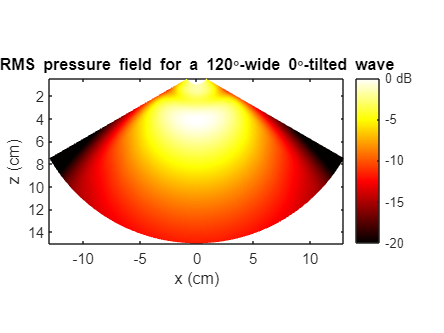


for D2R = 10:10:120
%% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,64)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(dw,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
            '-wide 0{\circ}-tilted wave'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
        saveas(gcf,['Pressure field image degree wide ' num2str(D2R) '.jpg'])
end